## **Experiment 3: Linear Discriminant Analysis**

**1、绘制图例**

blue = load ("ex3blue.dat") ;
red = load ("ex3red.dat"); 
green = load("ex3green.dat");
% 绘制 blue 点
scatter(blue(:,1), blue(:,2), 'b','filled');
hold on; % 保持当前图像
% 绘制 red 点
scatter(red(:,1), red(:,2), 'r','filled');
hold on;
scatter(green(:,1), green(:,2), 'g','filled');

2、计算blue和red的两个数据集的重心点miu1，miu2

miu1 = [0;0];
miu2 = [0;0];
miu3 = [0;0];
for i = 1 :14
    miu1 = miu1 + [blue(i,1); blue(i,2)];
    miu2 = miu2 + [red(i, 1); red(i, 2)];
    miu3 = miu3 + [green(i,1); green(i,2)];
end
miu1 = miu1/14;
miu2 = miu2/14;
miu3 = miu3/14;
miuall = miu1 + miu2 + miu3;

3、计算Sw,Sb矩阵

sw = zeros(2,2);
for i = 1: 14
    sw = sw + (blue(i,:)' - miu1)*(blue(i,:)' - miu1)';
    sw = sw + (red(i, :)' - miu2)*(red(i,:)' - miu2)';
    sw = sw + (green(i, :)' - miu3)*(green(i,:)' - miu3)';
end
sb = zeros(2,2);
sb  = sb + 14*(miu1 - miuall)*(miu1 - miuall)';
sb  = sb + 14*(miu2 - miuall)*(miu2 - miuall)';
sb  = sb + 14*(miu3 - miuall)*(miu3 - miuall)';
vector = inv(sw)*sb;
[V, d] = eig(vector);

4、计算θ

theta = -V(:,2);
theta = theta/sqrt(theta(1)*theta(1) + theta(2)*theta(2))

theta =     0.8542
    0.5200


5、画出θ曲线

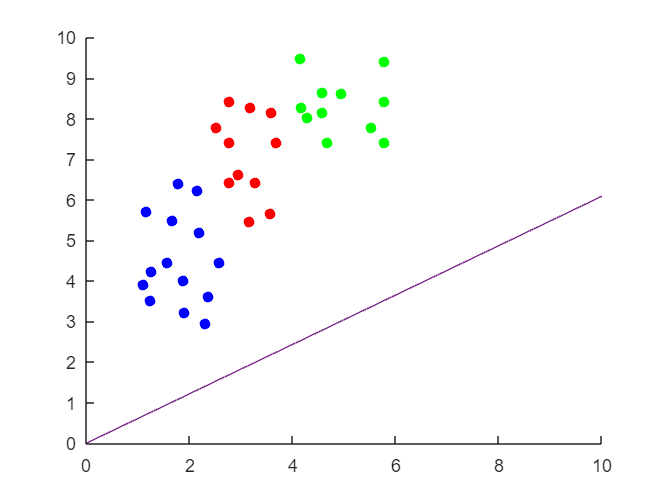

x = linspace(0, 10, 100);
k = theta(2)/theta(1);
y = x * k;
plot(x, y);

6、画出投影点

% for i = 1 : 14
%     blue2(i) = theta(1) * blue(i, 1) + theta(2) * blue(i, 2);
%     blue3(i) = blue2(i)/sqrt(1+k^2);
%     red2(i) = theta(1) * red(i, 1) + theta(2) * red(i, 2);
%     red3(i) = red2(i)/sqrt(1+k^2);
%     green2(i) = theta(1) * green(i, 1) + theta(2) * green(i, 2);
%     green3(i) = green2(i)/sqrt(1+k^2);
% end
% scatter(blue3(:),k*blue3(:), 'b','filled');
% scatter(red3(:), k*red3(:) ,'r','filled');
% scatter(green3(:), k*green3(:) ,'g','filled');